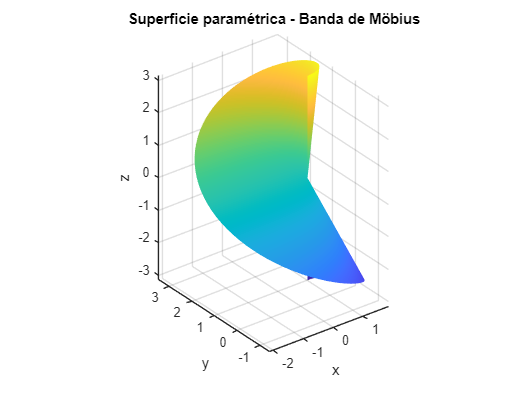

%% Actividad 2-2 - Superficies, Campos, Electricidad y Bisección
clc; clear; close all;

%% Inciso 1: Superficie Paramétrica
a = 1;
r = 0.5;
[u, v] = meshgrid(linspace(0, 2*pi, 100), linspace(0, 2*pi, 100));

x = a + r * v .* sin(u/2) .* cos(u);
y = a + r * v .* sin(u/2) .* sin(u);
z = r * v .* cos(u/2);

figure;
surf(x, y, z)
xlabel('x'); ylabel('y'); zlabel('z');
title('Superficie paramétrica - Banda de Möbius');
axis equal
shading interp

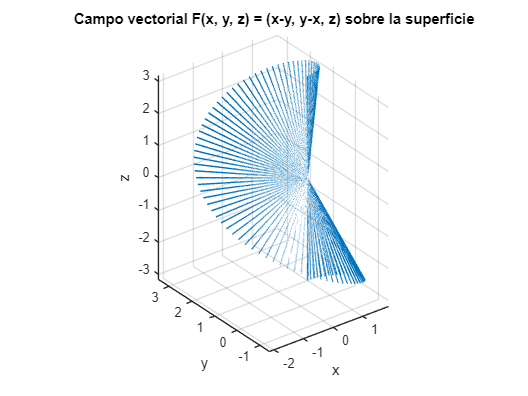


%% Inciso 2: Campo vectorial sobre la superficie
figure;
quiver3(x, y, z, x - y, y - x, z, 0.5)
xlabel('x'); ylabel('y'); zlabel('z');
title('Campo vectorial F(x, y, z) = (x-y, y-x, z) sobre la superficie');
axis equal

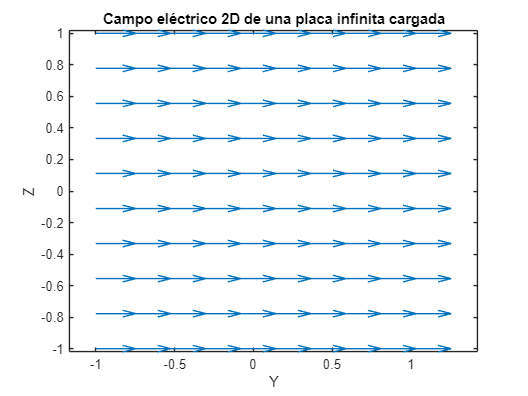


%% Inciso 3: Campo eléctrico de una placa infinita
sigma = 1.5;  % C/m^2
epsilon0 = 8.85e-12;  % F/m
E = sigma / (2 * epsilon0);  % Magnitud del campo

% 2D
[y2D, z2D] = meshgrid(linspace(-1, 1, 10), linspace(-1, 1, 10));
Ex2D = E * ones(size(y2D));
figure;
quiver(y2D, z2D, Ex2D, zeros(size(Ex2D)))
title('Campo eléctrico 2D de una placa infinita cargada');
xlabel('Y'); ylabel('Z');
axis equal

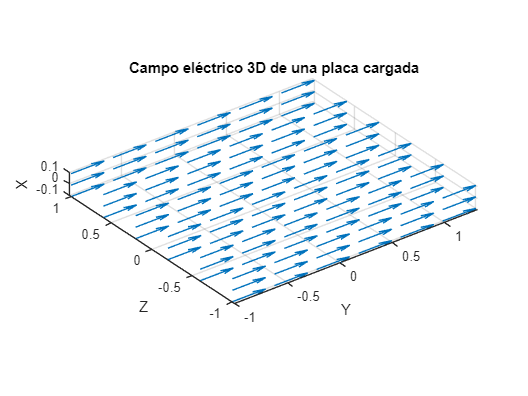


% 3D
[y3D, z3D, x3D] = meshgrid(linspace(-1,1,6), linspace(-1,1,6), linspace(-0.1,0.1,3));
Ex3D = E * ones(size(x3D));
figure;
quiver3(y3D, z3D, x3D, Ex3D, zeros(size(x3D)), zeros(size(x3D)))
title('Campo eléctrico 3D de una placa cargada');
xlabel('Y'); ylabel('Z'); zlabel('X');
axis equal


%% Inciso 4: Análisis del error en métodos de bisección y tri-sección
% a) Iteraciones necesarias para error < 1e-10 con bisección
error_deseado = 1e-10;
n_biseccion = ceil(log2(1 / error_deseado));

fprintf('Iteraciones requeridas con bisección: %d\n', n_biseccion);

Iteraciones requeridas con bisección: 34



% b) Error con tri-sección
n_triseccion = ceil(log(1 / error_deseado) / log(3));
fprintf('Iteraciones requeridas con tri-sección: %d\n', n_triseccion);

Iteraciones requeridas con tri-sección: 21


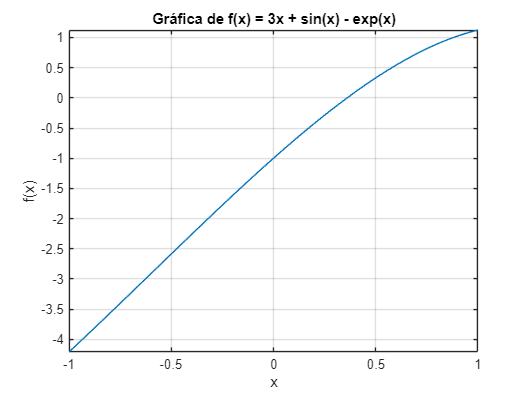


%% 🔹 Inciso 5: Método de Bisección para f(x) = 3x + sin(x) - exp(x)
f = @(x) 3*x + sin(x) - exp(x);

% Gráfica para encontrar intervalo adecuado
figure;
fplot(f, [-1, 1])
grid on
xlabel('x'); ylabel('f(x)');
title('Gráfica de f(x) = 3x + sin(x) - exp(x)');


% Usamos intervalo [0, 1] para bisección
[root, iter, valores] = biseccion(f, 0, 1, 0.001);
fprintf('Raíz encontrada: %.6f en %d iteraciones\n', root, iter);

Raíz encontrada: 0.360352 en 9 iteraciones


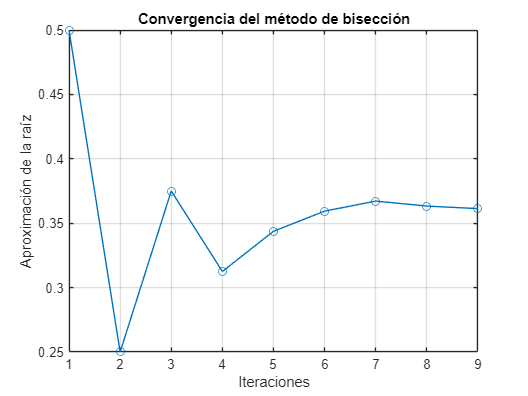


% Gráfica de convergencia
figure;
plot(1:iter, valores, '-o')
xlabel('Iteraciones')
ylabel('Aproximación de la raíz')
title('Convergencia del método de bisección')
grid on


%% Función del método de bisección
function [root, iterations, valores] = biseccion(f, a, b, tol)
    fa = f(a); fb = f(b);
    if fa * fb > 0
        error('El intervalo no contiene una raíz');
    end

    valores = [];
    iterations = 0;

    while (b - a)/2 > tol
        c = (a + b)/2;
        fc = f(c);
        valores(end+1) = c;

        if fc == 0
            break
        elseif fa * fc < 0
            b = c; fb = fc;
        else
            a = c; fa = fc;
        end
        iterations = iterations + 1;
    end
    root = (a + b)/2;
end